# DeepInterpolation - Tiny Ephys Inference Example

This example imports and uses the deep interpolation model in MATLAB for tiny ephys sample data.

## Find the deepinterpolation folder and add it to path

DI_path = uigetdir(pwd,'Select deepinterpolation folder')

DI_path = 'C:\Users\joris.bentvelsen\Documents\DeepInterpolation-MATLAB'

addpath(genpath(DI_path))

## Find the trained model

If not done so already, the pretrained model is downloaded.

trained_model_file = '2020_02_29_15_28_unet_single_ephys_1024_mean_squared_error-1050.h5';
if ~isfile(fullfile('sample_data', trained_model_file))
    dropboxFileURL = 'https://www.dropbox.com/sh/tm3epzil44ybalq/AACyKxfvvA2T_Lq_rnpHnhFma?dl=1';
    destinationFile = fullfile('sample_data',trained_model_file);
    try
        disp('Downloading trained model...');
        websave(destinationFile, dropboxFileURL);
        disp('Downloaded the trained model successfully.');
    catch ex
        disp('Error downloading the trained model.');
        throw(ex);
    end
else
    disp('Found the trained model')
end

Found the trained model


## Import and Assemble Model

Import the trained model.

importednet = importKerasLayers('2020_02_29_15_28_unet_single_ephys_1024_mean_squared_error-1050.h5','ImportWeights',true);

License checkout failed.
License Manager Error -10
Your license for Neural_Network_Toolbox has expired. 
If you are not using a trial license contact your License Administrator to obtain an updated license. 
Otherwise, contact your Sales Representative for a trial extension.

Troubleshoot this issue by visiting: 
<a href="https://www.mathworks.com/support/lme/10">https://www.mathworks.com/support/lme/10</a>

Diagnostic Information:
Feature: Neural_Network_Toolbox 
License path: C:\Users\joris.bentvelsen\AppData\Roaming\MathWorks\MATLAB\R2023a_licenses;C:\Program Files\MATLAB\R2023a\licenses\license.dat;C:\Program Files\MATLAB\R2023a\licenses\license_vortech53_308496_R2023a.lic;C:\Program Files\MATLAB\R2023a\licenses\trial_11213685_R2023a_Aljen.lic;C:\Program Files\MATLAB\R2023a\licenses\trial_11213685_R2023a_Joris.lic 
Licensing error: -10,32.

Error in 

deepinterpnet = assembleNetwork(importednet)

## Analyze Network

Optionally analyze the network

if false
    analyzeNetwork(deepinterpnet)
end


## Import Sample Ephys 

raw_data = memmapfile('ephys_tiny_continuous.dat2','Format','int16','Writable',true)
nb_probes = 384; % Number of probes
total_frame_per_movie = fix(length(raw_data.Data)/(nb_probes));

%  We calculate the mean and std of the data
local_data = single(raw_data.Data);
local_mean = mean(local_data);
local_std = std(local_data);


shape = [total_frame_per_movie, fix(nb_probes / 2), 2];
% shape = [nb_probes, 2, total_frame_per_movie]; % final shape of the data [384,2,x]

% Format the data to match the dimensions of a neuropixels probe
raw_data = memmapfile('ephys_tiny_continuous.dat2','Format',{'int16', shape,'x'},'Writable',true)
ephys = raw_data.Data.x; 

## We reorganize to follow true geometry of probe for convolution 

#### (Fig. 3 [https://doi.org/10.1101/2020.10.15.341602](https://doi.org/10.1101/2020.10.15.341602)) 

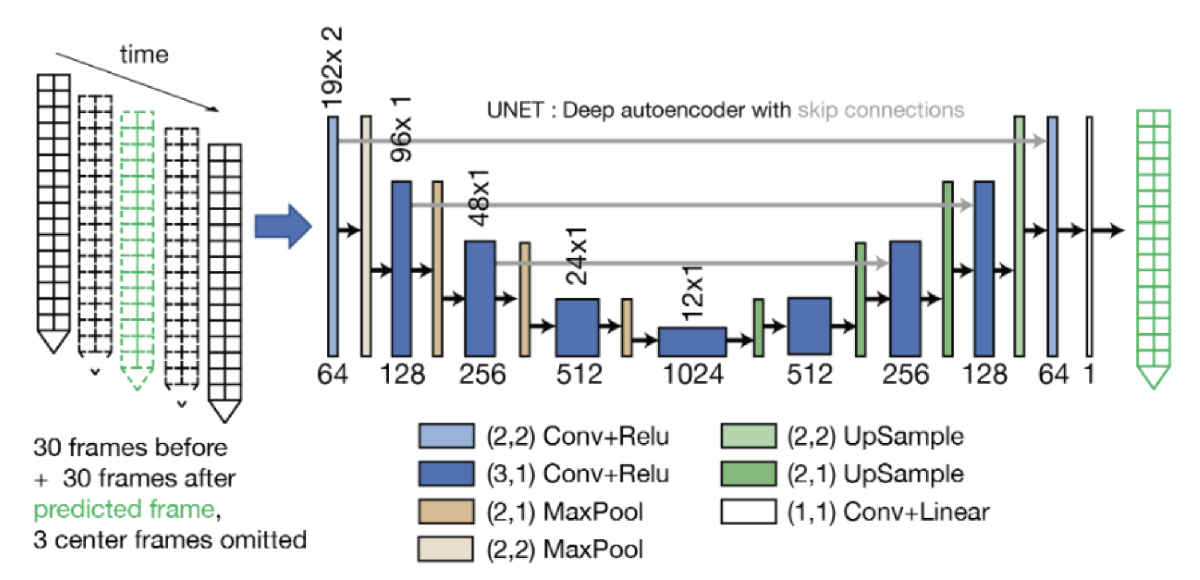

        
pre_post_omission = 1; % Number of frames omitted before and after the inferred frame

pre_frame = 30;  % Number of frames provided before the inferred frame
post_frame = 30; % Number of frames provided after the inferred frame

batch_size = 100;

start_frame = 100;

end_frame = 200;

input_full = single(zeros(batch_size, nb_probes, 2, pre_frame + post_frame));

for frame_index = start_frame:end_frame
    
    input_index = (frame_index - pre_frame - pre_post_omission) : (frame_index + post_frame + pre_post_omission );
    
    input_index = input_index(input_index ~= frame_index);   % drop the predicted frame 

    for index_padding = 1: pre_post_omission % drop pre_post_omission number of frames surrounding the predicted frame
        input_index = input_index(input_index ~= frame_index - index_padding);
        input_index = input_index(input_index ~= frame_index + index_padding);
    end

    data_img_input = ephys(input_index, :, :);
    
    data_img_input = permute(data_img_input,[2,3,1]);
    
    data_img_input = (single(data_img_input) - local_mean) / local_std;
    
    % alternating filling with zeros padding
    odd = 1: 2: nb_probes;
    even = odd + 1;
    
    input_full(frame_index-start_frame+1, odd, 1, :) = data_img_input(:, 1, :);
    input_full(frame_index-start_frame+1, even, 2, :) = data_img_input(:, 2, :);
 

end     

## Make Prediction

The network expects an input of size:

net_size = importednet.Layers(1).InputSize

The size of the ephys input data is:

size(input_full)

Make prediction (inference) with the equivalent size:

input = permute(input_full,[2,3,4,1]) ; % Note that batchsize is the last dimension here
try
    output = predict(deepinterpnet,input);
    output = permute(output,[4,1,2,3]);
    disp('Output size = ')
    disp(size(output));
    
catch
    warning('Error using predict. Returning null.');
    output = [];
end

## Plot inference results

input_fr = input_full(:,:,:,pre_frame+pre_post_omission);
input_frames = zeros(end_frame-start_frame+1,nb_probes);
% combine the 2 columns of neuropixels into 1 
input_frames(:,1:fix(nb_probes/2)) = input_fr(:,odd,1);
input_frames(:,(fix(nb_probes/2)+1):nb_probes) = input_fr(:,even,2);

% we had earlier filled half of the channels with zeros to match probe geometry
% now we take only the non-zero channels 
output_frames = zeros(end_frame-start_frame+1,nb_probes);
% combine the 2 columns of neuropixels into 1 
output_frames(:,1:fix(nb_probes/2)) = output(:,odd, 1);
output_frames(:,(fix(nb_probes/2)+1):nb_probes) = output(:,even, 2);


hFig = figure; 
hAxRef = subplot(1,2,1); 
hImRef = imagesc(input_frames'); 
hAx = subplot(1,2,2); 
hIm = imagesc(hAx,output_frames'); 
set(hAxRef,'CLim',hAx.CLim)
subplot(1,2,1)
colorbar
xlabel('Sample Number')
ylabel('Channel Number')
title('Original')
subplot(1,2,2)
colorbar
xlabel('Sample Number')
ylabel('Channel Number')
title('DeepInterpolation')

figure
channel =235;
plot(input_frames(:,channel))
hold on
plot(output_frames(:,channel))
legend('Original','DeepInterpolation')
xlabel('Sample Number')
ylabel("Normalized Amplitude ('�V')")